**Assignment-3b **

`Companion Book MATLAB Problems `

`1.4 Properties of Discrete-Time Systems In this exericise you will practice using MATLAB to construct such counter-examples demonstrate that the system fails to satisfy the property in question. `

`(a) The system `$y[n]=sin(\pi/2x[n])$`is not linear. Use the signals `$x_1[n]=\delta[n] \ and\ x_2[n]=\delta[2n]$` to demonstrate how the system violates linearity. `

n=[-10:10];
delta1=((n)==0);
delta2=((2*n)==0);
a=2; b=3;
y1= sin(pi/2*delta1);
y2=sin(pi/2*delta2);
y3= a*y1+b*y2;
y3n=sin(pi/2*(a*delta1+b*delta2));
isequal(y3,y3n)

ans = logical
   0


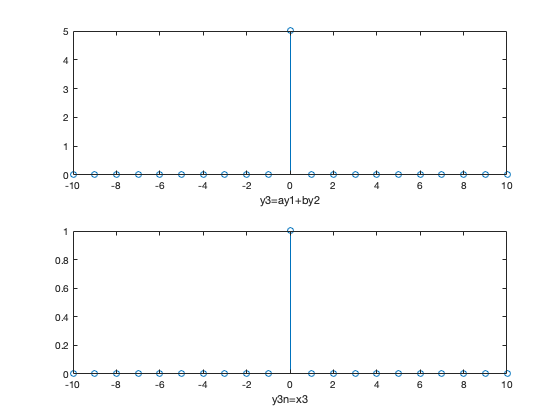


figure(1);
subplot(2,1,1); stem(n,y3); xlabel('y3=ay1+by2')       %I add labels for x axis
figure(1);
subplot(2,1,2); stem(n,y3n); xlabel('y3n=x3')          %I add labels for x axis

**1.4a Results analysis**

`We can see from isequal result and  from the graph that is above, the system is not linear.`

`(b) The system `$y[n]=x[n]+x[n+1]$ `is not causal. Use the singal `$x[n]=u[n]$ `to demonstrate this . Define the MATLAB vectors x and y to represent the input on the interval `$-5\leq n\leq 9$`, and the output on the interval `$-6\leq n\leq 9$`. `

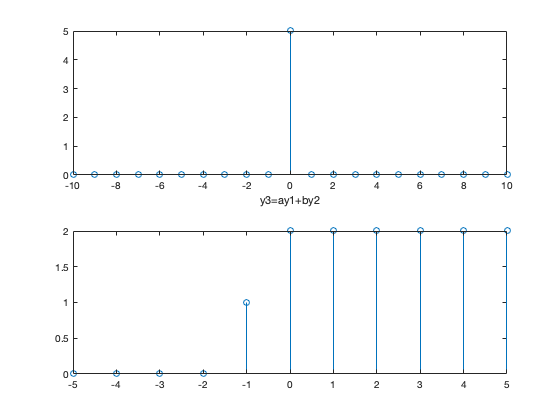

%
%   The system is combined version of x[n] and x[n+1] 
%   input defined at range of -5<= n <=9 but output -6<= n <=9
%   because of that cannot be Causal and has memory
%

n = -5 : 5;
y = heaviside(n)+heaviside(n+1);
stem(n, y);

`1.4(b) Results Analysis: `

`Te plot shows, y[n] is depend of the future value of x[n], so it is not causal.`

`(c ) The system `$y[n]=log(x[n])$`is not stable `

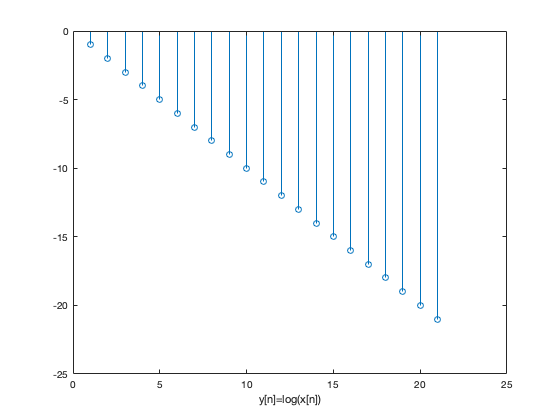

%
%   Log(x[n]) is not bounded because infinite <= log(x[n])
%   We can see from the graph it has no boundaries
%
clf;
n=[1:21];
x=n*1.0;
a=-1;
for k=1:21                  % I think your bounded input was much clear 
 x(k)=exp(a*k);
end
xn=log(x);
stem(n,xn); xlabel('y[n]=log(x[n])'); % I forgot to put label to x axis

`1.4c Results Analysis: `

`From the plot, given a bounded input with a = -1, the y becomes unbounded. So this is a counter example showing y[n] is not stable.`

`(d) The system given in Part (a) is not invertible`

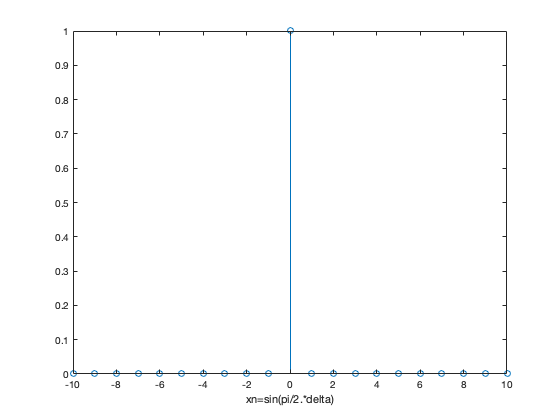

%
%   A system is invertible, if unique (distinct) inputs produce unique (distinct) outputs, 
%   otherwise it not invertible.
%   
%   The signal, sin((pi/2)*x[n]), is not invertible when x[n]= delta[n]
%   Because of definition of delta function can not produce unique outputs. 
%  
%   Also sine function can be invertible only when its defined between -pi/2 and pi/2
%


n=[-10:10];
delta=((n)==0);
xn=sin(pi/2.*delta);
stem(n,xn);  xlabel('xn=sin(pi/2.*delta)')   % I forgot to put label

`1.4d Results Analysis: `

`A system is invertible if distinct inputs lead to disinct outputs. We can see from plot, the signal output is not disinct.Therefore the system is not invertible.`

`Advanced Problems `

`For each of the following systems, state whether of not the system is linear, time-invariant, causal, stable, and invertible. You only need to show at least one preporty that system does not possecess by a counter-example using MATLAB. `

`(e)`$y[n]=x^3[n]$` . Hint: `$(a+b)^3= a^3+3a^2b+3ab^2+b^3$

%
%   Lets check linearity,
%   define y1= x1^3[n]
%   define y2= x2^3[n]
%   define y3= x3^3[n]
%   check y3= ay1+by2
%   y3 = ( ax1[n] + bx2[n])^3 = a^3x1^3+ 3(a^2x1^2)(bx2)+3(ax1)(b^2x2)+b^3x^3
%   It is clear that the system is not linear
%   

n=[1:10];
a=1;
b=2;
y1=n.^3;
y2=n.^3;
y3= a.*y1+b.*y2;
y3n= a^3.*y1 + 3*(a^2).*(y1.^2).*b.*y2 + 3*a.*y1.*(b^2).*(y2.^2)+ y2.^3;
isequal(y3,y3n) % They are not equal because of that the system is not linear.

ans = logical
   0


**1.4e Results analysis**

`We can see from isequal result and  from the graph that is above, the system is not linear.`

`(f) `$y[n]=nx[n]$

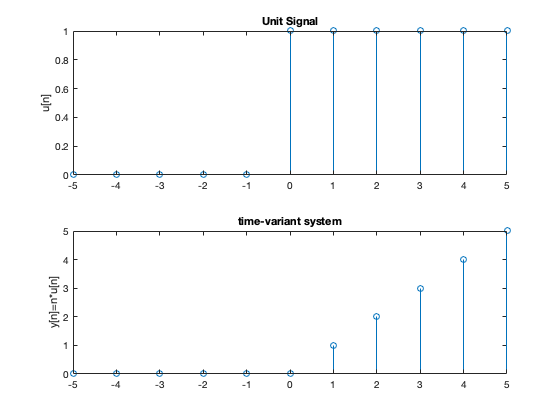

%
%  y[n]=nx[n] is not invertible and time-variant
%
%   We can see from the graph the y[n] is not time variant
%
n=[-5:5];
xn=heaviside(n);
yn=n.*xn;

figure(1);
subplot(2,1,1);
stem(n,xn);
title('Unit Signal');
ylabel('u[n]');

figure(1);
subplot(2,1,2);
stem(n,yn);
title('time-variant system');
ylabel('y[n]=n*u[n]');

**1.4f Results analysis**

`We can see from plot y[n] is not time-invariant.`

`(g) `$y[n]=x[2n]$

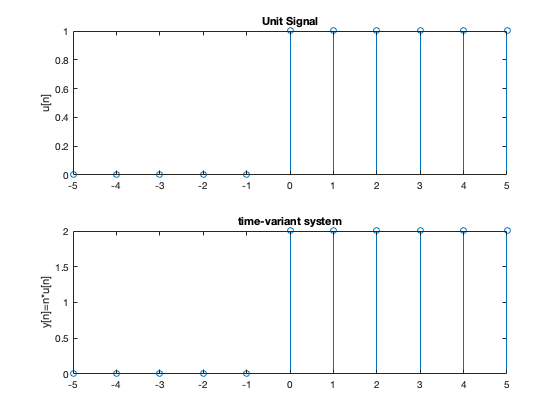

%
%
%
%   The system is not Casual because y(1)=x(2), This implies, the
%   system depend on future for that reason it is not causal
%   
%
%

n=[-5:5];
xn=heaviside(n);
yn=2.*xn;

figure(1);
subplot(2,1,1);
stem(n,xn);
title('Unit Signal');
ylabel('u[n]');

figure(1);
subplot(2,1,2);
stem(n,yn);
title('time-variant system');
ylabel('y[n]=n*u[n]');

**1.4g Results analysis**

`We can see from plot,depends on future input.(y(1)=x(2))`

`1.6 Continous-Time Complex Exponential Signals`

` Complex exponentials are particularly useful for analyzing signals and systems, since they form the building blocks for a large class of signals. Two familar signals which can be expressed as a sum of complex exponentials are consine and sine. Let consider the continous-time complex expoential signals which have the form . For example, by setting we obtain: `

                      $cos(\omega t)=\frac{1}{2}(e^{i\omega t}+e^{-i\omega t})$`        (1.7)                                                 `

                      $sin(\omega t)=\frac{1}{2i}(e^{i\omega t}-e^{-i\omega t})$`        (1.8)                                              `

`In this exercise, you will be asked to use the Symbolic Math Toolbox. `

`Basic Problems `

`(a). Consider the continous-time sinusoid, `$x(t)=sin(2\pi t/T)$` . A symbolic expression can be created to represent `$x(t)$` within MATLAB by executing `

`>> x = sym(sin(2*pi*t/T)); `

`If you desire T=5, you can use subs as follows: `

`>> x5 = subs(x, T, 5); `

`Note: both lines of code are slitly different from the companion book to avoid a compiling error`

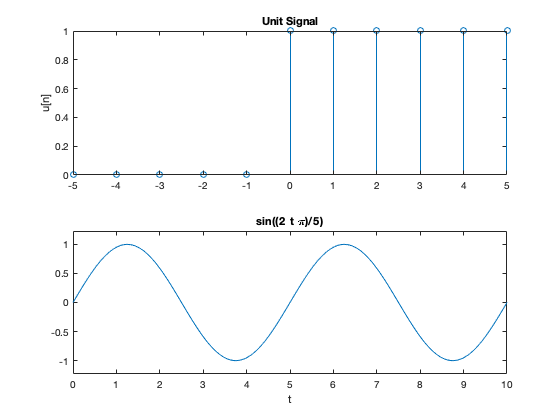

syms t T

y=sin(2*pi*t/T);
x5=subs(y,T,5);
ezplot(x5,[0 10]);

`(b). Create a symbolic expression for the signal `$x(t)=cos(2\pi t/T)sin(2\pi t/T)$` For T=4, 8, and 16, use ezplot to plot the signal on the interval `$0\leq t\leq 32$` . What is the fundamental period of x(t) in terms of T?`

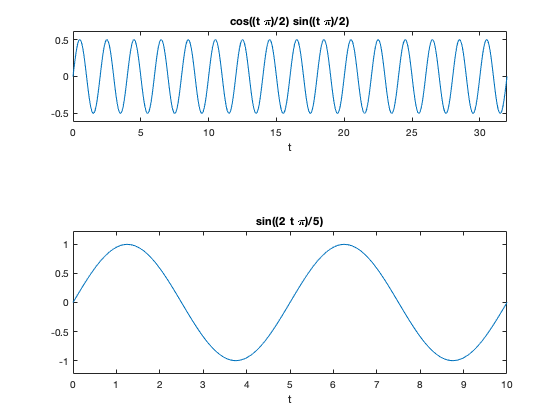

n=[0:32];
syms t T

xt=cos(2*pi*t/T).*sin(2*pi*t/T);

x4=subs(xt,T,4);
figure(1);
subplot(3,1,1); 
ezplot(x4,n);

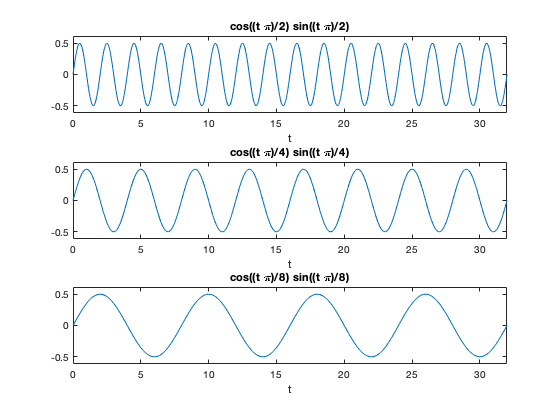


x8=subs(xt,T,8);
figure(1);
subplot(3,1,2); 
ezplot(x8,n);


x16=subs(xt,T,16);
figure(1);
subplot(3,1,3); 
ezplot(x16,n);

`Intermediate Problem`

` (c ). Create a symbolic expression for th signal `$x(t)=e^{-at}cos(2\pi t)$` . For `$a=1/2,1/4 \ and \ 1/8$`, use ezplot to determine `$t_d$`, time time at which `$\mid x(t) \mid$` last crossed 0.1. Define `$t_d$ `as the time at which the signal dies out. Use ezplot to determine for each value of a how many complete periods of the cosine occur before the signal diew out. Does the number of periods appear to be proportional to Q?`

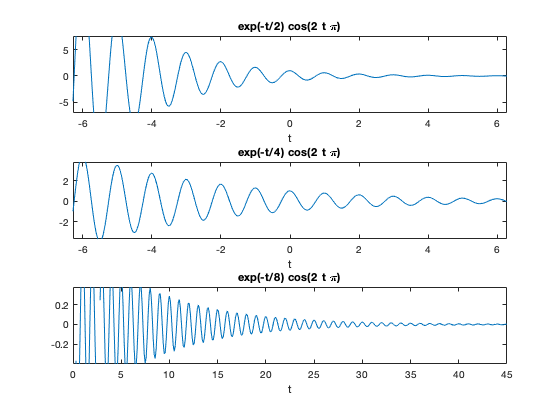

syms t a

xt=exp(-a*t)*cos(2*pi*t);
xa1=subs(xt,a,1/2);

figure(1);
subplot(3,1,1);
ezplot(xa1);

figure(1);
subplot(3,1,2);
xa4=subs(xt,a,1/4);
ezplot(xa4);

figure(1);
subplot(3,1,3);
xa8=subs(xt,a,1/8);
ezplot(xa8,[0 45]); % I put a range to see the changes better like you 

function y = heaviside(n)
% We assume a vector input 

% Our default output value is 0
y = 0 * n;
% Now, we find values in n greater than or equal to 0
y(find(n >= 0)) = 1;

end